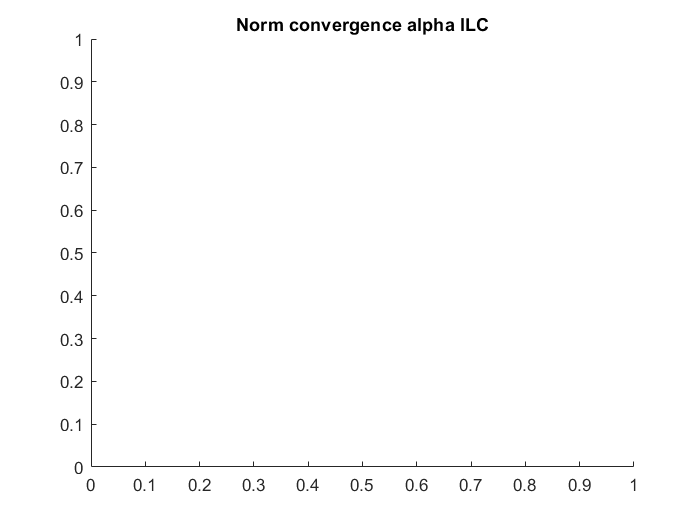

clear all; close all; clc;
warning('off','all');

gamma_gain = 0.5;

fc = 100; %30 hz and 4 order
order = 4;
tSample = 1e-4;
fs = 1/tSample;

[b,a] = butter(order,fc/(fs/2)); %0.02 -> *500 Hz 
[A2,B2,C2,D2] = tf2ss(b,a);
Q_filter = ss(A2,B2,C2,D2,1/fs);

maxiterations = 10;
FF_start = 1;

figure(1)
title('Norm convergence alpha ILC')


for i = 1:maxiterations
    [norm_e, FF_start] = alpha_ILC(i-1, gamma_gain, FF_start, Q_filter)
    
    figure(1)
    hold on;
    plot(i,norm_e)
    
end

Error using NewMain
Too many input arguments.